clc;
clear;
close all;

%% Image Parameters
width = 1920;
height = 1080;
channels_rgb = 3;
bits_per_pixel = 8;

%% Storage Calculations
image_bits = width * height * channels_rgb * bits_per_pixel;
image_bytes = image_bits / 8;
image_MB = image_bytes / (1024^2);

total_images = 50;
total_storage_MB = image_MB * total_images;

fprintf('Storage Per RGB Image: %.2f MB\n', image_MB);

Storage Per RGB Image: 5.93 MB


fprintf('Total Storage for 50 Images: %.2f MB\n\n', total_storage_MB);

Total Storage for 50 Images: 296.63 MB



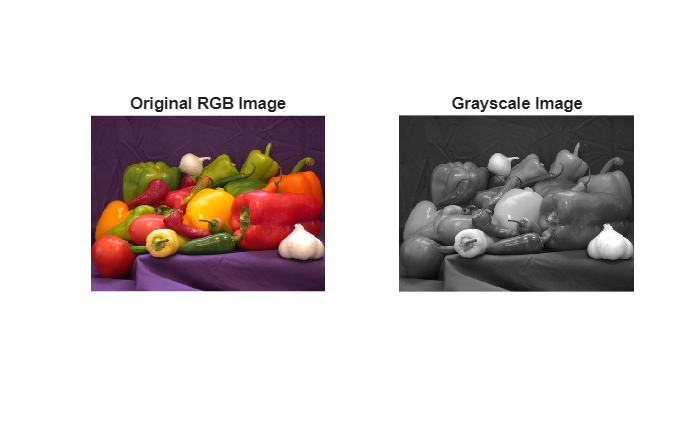


%% Read and Convert Image (Use built-in image)
rgb_image = imread('peppers.png');   % Built-in MATLAB image
gray_image = rgb2gray(rgb_image);

%% Display Images
figure;
subplot(1,2,1);
imshow(rgb_image);
title('Original RGB Image');

subplot(1,2,2);
imshow(gray_image);
title('Grayscale Image');


%% Grayscale Storage Calculation
gray_bits = width * height * bits_per_pixel;
gray_bytes = gray_bits / 8;
gray_MB = gray_bytes / (1024^2);

%for 50 grayscale images
gray_storage_MB = gray_MB * total_images;

fprintf('Grayscale Image Storage: %.2f MB\n', gray_MB);

Grayscale Image Storage: 1.98 MB


fprintf('Total Storage for 50 Grayscale Images: %.2f MB\n\n', gray_storage_MB);

Total Storage for 50 Grayscale Images: 98.88 MB




%% Storage Reduction
reduction_percentage = ((image_MB - gray_MB) / image_MB) * 100;
fprintf('Storage Reduction after Grayscale Conversion: %.2f %%\n', reduction_percentage);

Storage Reduction after Grayscale Conversion: 66.67 %
